# **LAB: Bearing Fault Diagnosis**

- Thomas W. Rauber et al. "Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis", IEEE TRANSACTIONS ON INDUSTRIAL ELECTRONICS, VOL. 62, NO. 1, JANUARY 2015

- Using CWRU data set

#### Data Acquisition

clear
close all
clc

data_acquisition()

#### Statistical Features

statistical_Features()

stat_table = 150×27 table
    DE rms      DE sra       DE sk       DE kt     DE ppv     DE if     DE sf     DE cf     DE mf     DE kf       DE fc        DE rmsf        DE rvf      FE rms      FE sra       FE sk      FE kt     FE ppv    FE if     FE sf     FE cf     FE mf     FE kf       FE fc        FE rmsf        FE rvf        Class  
    _______    ________    __________    ______    _______    ______    ______    ______    ______    ______    __________    __________    __________    _______    ________    _________    ______    ______    ______    ______    ______    ______    ______    __________    __________    __________    _________

    0.13699    0.093363     -0.017602    2.9497     1.0295    4.7406    1.2478    3.7991    5.5744    8375.5    9.2579e-05    0.00051631    0.00050795    0.18101    0.098149     0.036041    11.389    2.9874    12.794    1.4692    8.7087    16.061     10609    0.00022739    0.00084646    0.00081534    "Ball_07"
     0.1404    0.094967     -0.044965

#### Complex Envelope Analysis

envelop_feature()

env_table = 150×73 table
    DEInner_DE_1st    DEOuter_DE_1st    DEFSB_DE_1st    DEInner_FE_1st    DEOuter_FE_1st    DEFSB_FE_1st    DEInner_DE_ 2nd    DEOuter_DE_ 2nd    DEFSB_DE_ 2nd    DEInner_FE_ 2nd    DEOuter_FE_ 2nd    DEFSB_FE_ 2nd    DEInner_DE_ 3th    DEOuter_DE_ 3th    DEFSB_DE_ 3th    DEInner_FE_ 3th    DEOuter_FE_ 3th    DEFSB_FE_ 3th    DEInner_DE_ 4th    DEOuter_DE_ 4th    DEFSB_DE_ 4th    DEInner_FE_ 4th    DEOuter_FE_ 4th    DEFSB_FE_ 4th    DEInner_DE_ 5th    DEOuter_DE_ 5th    DEFSB_DE_ 5th    DEInner_FE_ 5th    DEOuter_FE_ 5th    DEFSB_FE_ 5th    DEInner_DE_ 6th    DEOuter_DE_ 6th    DEFSB_DE_ 6th    DEInner_FE_ 6th    DEOuter_FE_ 6th    DEFSB_FE_ 6th    FEInner_DE_1st    FEOuter_DE_1st    FEFSB_DE_1st    FEInner_FE_1st    FEOuter_FE_1st    FEFSB_FE_1st    FEInner_DE_ 2nd    FEOuter_DE_ 2nd    FEFSB_DE_ 2nd    FEInner_FE_ 2nd    FEOuter_FE_ 2nd    FEFSB_FE_ 2nd    FEInner_DE_ 3th    FEOuter_DE_ 3th    FEFSB_DE_ 3th    FEInner_FE_ 3th    FEOuter_FE_ 3th    FEFSB_FE_ 

#### Wavelet Package Analysis

WaveletPacket_feature()

wp_table = 150×33 table
    DE_E1     DE_E2     DE_E3     DE_E4     DE_E5     DE_E6     DE_E7      DE_E8       DE_E9       DE_E10     DE_E11      DE_E12     DE_E13    DE_E14    DE_E15     DE_E16     FE_E1     FE_E2      FE_E3     FE_E4     FE_E5     FE_E6      FE_E7     FE_E8      FE_E9       FE_E10     FE_E11     FE_E12     FE_E13    FE_E14    FE_E15    FE_E16      Class  
    ______    ______    ______    ______    ______    ______    ______    _______    _________    ________    _______    ________    ______    ______    _______    _______    ______    ______    _______    ______    ______    ______    _______    ______    ________    ________    _______    _______    ______    ______    ______    ______    _________

    2.5717    4.0286    1.4702    1.7596    22.926    10.471    1.0971    0.77436    0.0047622    0.038398     0.1627     0.05165    35.596    17.468     0.5222     1.0568    4.4635    2.9196    0.47158    2.7028    9.9604    13.668    0.59829     1.923    0.083568    

#### Global Pool

Global_pool()

global_pool = 150×131 table
    DE rms      DE sra       DE sk       DE kt     DE ppv     DE if     DE sf     DE cf     DE mf     DE kf       DE fc        DE rmsf        DE rvf      FE rms      FE sra       FE sk      FE kt     FE ppv    FE if     FE sf     FE cf     FE mf     FE kf       FE fc        FE rmsf        FE rvf      DE_E1     DE_E2     DE_E3     DE_E4     DE_E5     DE_E6     DE_E7      DE_E8       DE_E9       DE_E10     DE_E11      DE_E12     DE_E13    DE_E14    DE_E15     DE_E16     FE_E1     FE_E2      FE_E3     FE_E4     FE_E5     FE_E6      FE_E7     FE_E8      FE_E9       FE_E10     FE_E11     FE_E12     FE_E13    FE_E14    FE_E15    FE_E16    DEInner_DE_1st    DEOuter_DE_1st    DEFSB_DE_1st    DEInner_FE_1st    DEOuter_FE_1st    DEFSB_FE_1st    DEInner_DE_ 2nd    DEOuter_DE_ 2nd    DEFSB_DE_ 2nd    DEInner_FE_ 2nd    DEOuter_FE_ 2nd    DEFSB_FE_ 2nd    DEInner_DE_ 3th    DEOuter_DE_ 3th    DEFSB_DE_ 3th    DEInner_FE_ 3th    DEOuter_FE_ 3th    DEFSB_FE_ 3th    DEInner

## Experiment Output: Accuracy & Confusion Matrix

### EX1. Without Selection

- Features:Statistical / Envelope / WPT / Global Pool

- Classifer: SVM / K-NN / Decision Tree

### Normalization

The weight of each feature is different, so relatively small values can be ignored when classifying, so normalization was performed.

stat_table(:,1:end-1)  = normalize(stat_table(:,1:end-1),'range');
env_table(:,1:end-1)   = normalize(env_table(:,1:end-1),'range');
wp_table(:,1:end-1)    = normalize(wp_table(:,1:end-1),'range');
global_pool(:,1:end-1) = normalize(global_pool(:,1:end-1),'range');

#### Statistical Features

- Divide Statistical Features into Train set and Test set 

[stat_Train, stat_Train_class, stat_Test, stat_Test_class] = Train_Test(stat_table);

    - K-NN 

ResubErr_KNN = 0

cvErr_KNN = 0.1429

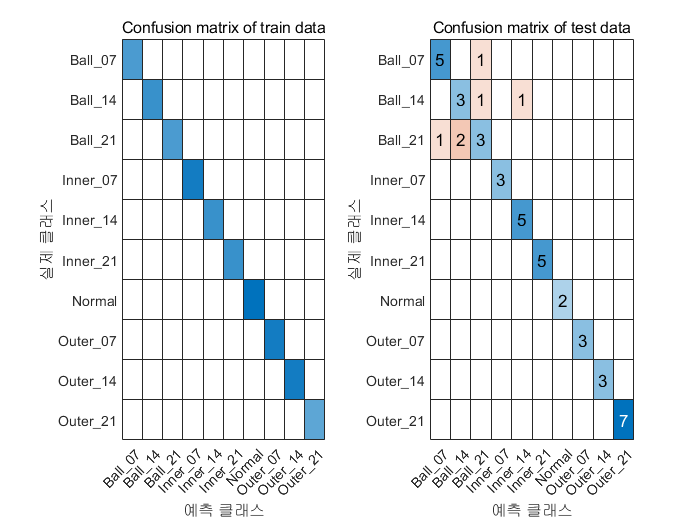

stat_KNN_loss = 0.0952

stat_KNN_loss = KNN(stat_Train,stat_Train_class,stat_Test, stat_Test_class)

    - SVM 

ResubErr_SVM = 0.0571

cvErr_SVM = 0.1143

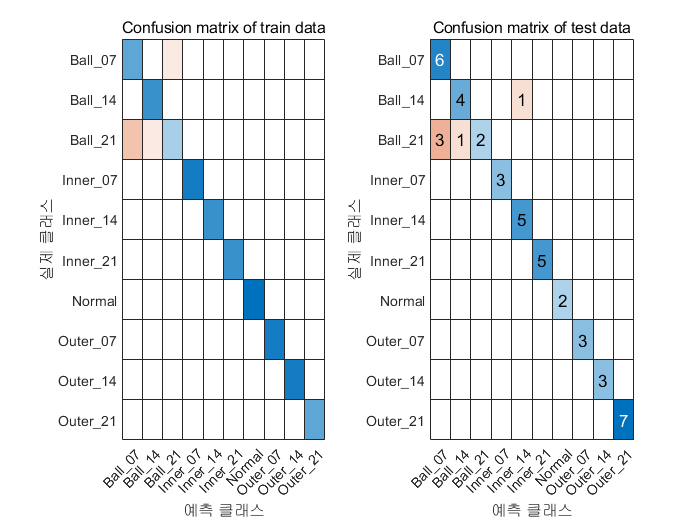

stat_SVM_loss = 0.0762

stat_SVM_loss = SVM(stat_Train,stat_Train_class,stat_Test, stat_Test_class)

    - Decision Tree

ResubErr_Tree = 0

cvErr_Tree = 0.0762

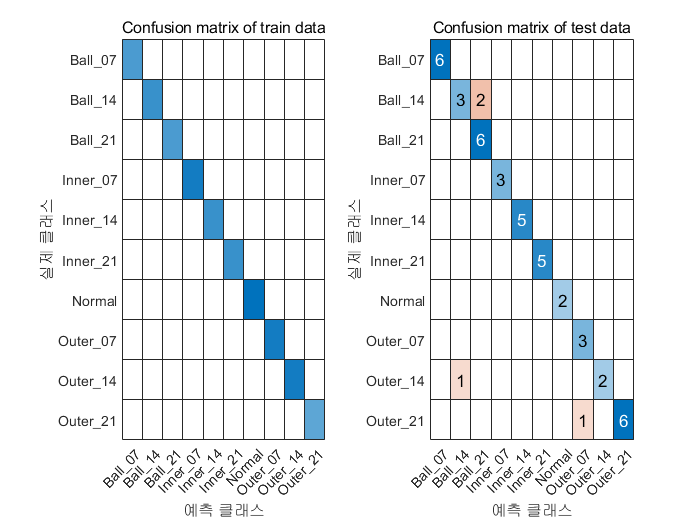

stat_Tree_loss = 0.0871

stat_Tree_loss = Decision_Tree(stat_Train,stat_Train_class,stat_Test, stat_Test_class)

#### Envelope Features

- Divide into Train set and Test set

[env_Train, env_Train_class, env_Test, env_Test_class] = Train_Test(env_table);

  - K-NN 

ResubErr_KNN = 0

cvErr_KNN = 0.0095

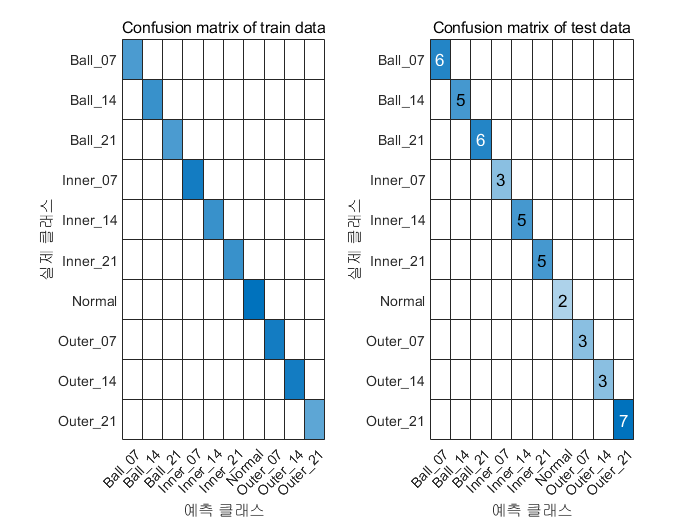

env_KNN_loss = 0

env_KNN_loss = KNN(env_Train,env_Train_class,env_Test, env_Test_class)

  - SVM 

ResubErr_SVM = 0

cvErr_SVM = 0

env_SVM_loss = 0

env_SVM_loss = SVM(env_Train,env_Train_class,env_Test, env_Test_class)

   - Decision Tree

ResubErr_Tree = 0

cvErr_Tree = 0.0381

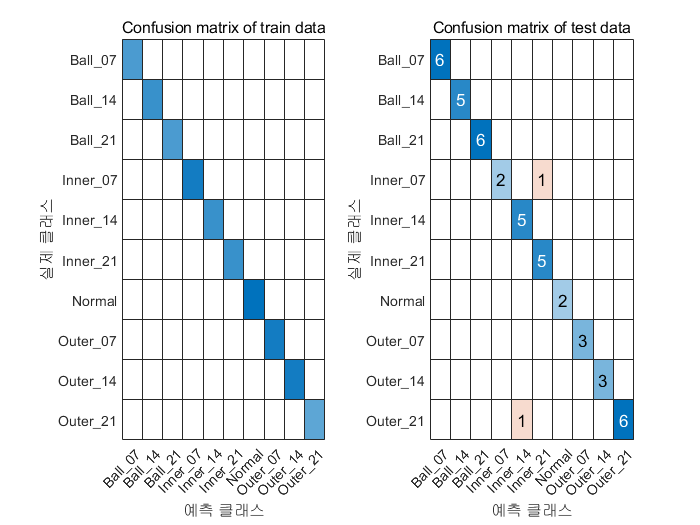

env_Tree_loss = 0.0490

env_Tree_loss = Decision_Tree(env_Train,env_Train_class,env_Test, env_Test_class)

#### Wavelet Features

- Divide into Train set and Test set

[wp_Train, wp_Train_class, wp_Test, wp_Test_class] = Train_Test(wp_table);

   - K-NN 

ResubErr_KNN = 0

cvErr_KNN = 0

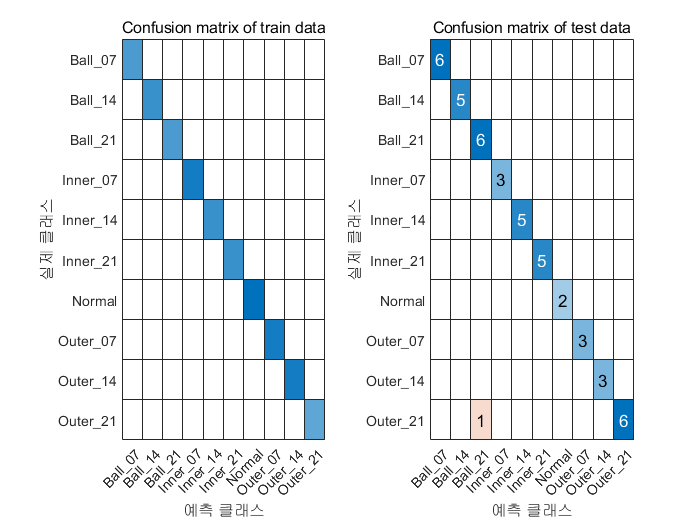

wp_KNN_loss = 0.0109

wp_KNN_loss = KNN(wp_Train,wp_Train_class,wp_Test, wp_Test_class)

  - SVM 

ResubErr_SVM = 0

cvErr_SVM = 0

wp_SVM_loss = 0

wp_SVM_loss = SVM(wp_Train,wp_Train_class,wp_Test, wp_Test_class)

   - Decision Tree

ResubErr_Tree = 0

cvErr_Tree = 0.0476

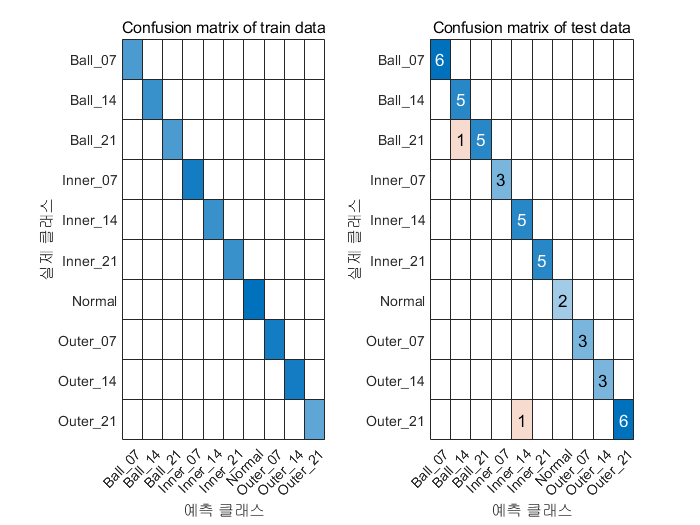

wp_Tree_loss = 0.0252

wp_Tree_loss = Decision_Tree(wp_Train,wp_Train_class,wp_Test, wp_Test_class)

#### Global Pool Features

- Divide into Train set and Test set

[global_Train, global_Train_class, global_Test, global_Test_class] = Train_Test(global_pool);

   - K-NN 

ResubErr_KNN = 0

cvErr_KNN = 0

pool_KNN_loss = 0

pool_KNN_loss = KNN(global_Train,global_Train_class,global_Test, global_Test_class)

 - SVM 

ResubErr_SVM = 0

cvErr_SVM = 0

pool_SVM_loss = 0

pool_SVM_loss = SVM(global_Train,global_Train_class,global_Test, global_Test_class)

  - Decision Tree

ResubErr_Tree = 0

cvErr_Tree = 0.0571

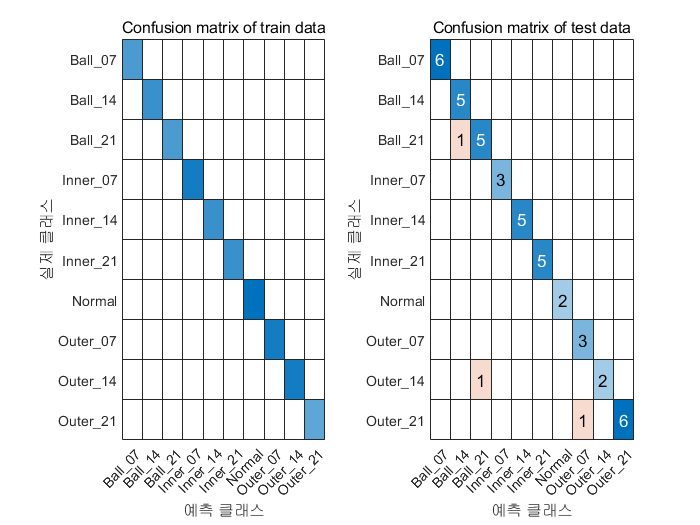

pool_Tree_loss = 0.0633

pool_Tree_loss = Decision_Tree(global_Train,global_Train_class,global_Test, global_Test_class)

### EX2. With Selection/Reduction

- Features: Global Pool

- Selection: PCA / Forward selection

- Classifer: SVM / K-NN / Decision Tree

### PCA

[coeff, scores_train, ~, ~, explained, pcaCenter] = pca(table2array(global_Train));

explain_standard = 0.95;     
num = find(cumsum(explained)/sum(explained) >= explain_standard, 1)

num = 14


coeff = coeff(:,1:num);
scores_train = scores_train(:,1:num);

[n,p] = size(global_Train);
meanX = mean(table2array(global_Train),1);

% Xfit: in original coordinate system
Xfit = repmat(meanX,n,1) + scores_train(:,1:num)*coeff(:,1:num)';

[ntest,ptest] = size(global_Test(:,1:end-1));
mu = repmat(pcaCenter, ntest, 1);
global_test_pca = (table2array(global_Test(:,1:end-1)) - mu)/coeff';

- KNN

ResubErr_KNN = 0

cvErr_KNN = 0.0190

PCA_KNN_loss = 0

PCA_KNN_loss = KNN(scores_train,global_Train_class,global_test_pca, global_Test_class)

- SVM

ResubErr_SVM = 0

cvErr_SVM = 0

PCA_SVM_loss = 0

PCA_SVM_loss = SVM(scores_train,global_Train_class,global_test_pca, global_Test_class)

- Decision Tree

ResubErr_Tree = 0

cvErr_Tree = 0.0095

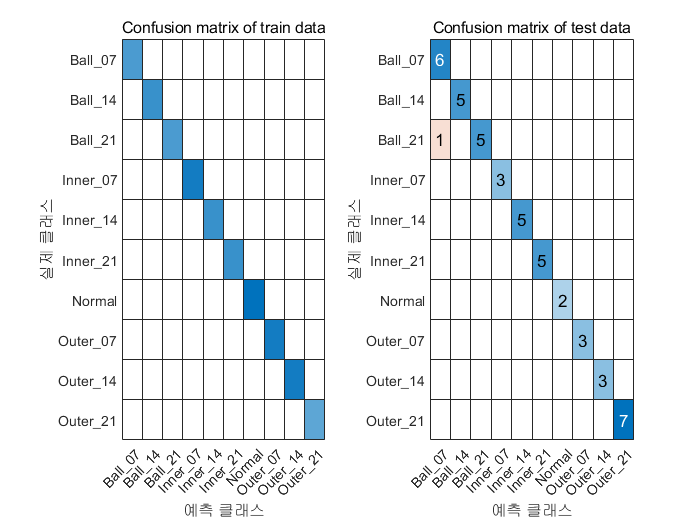

PCA_Tree_loss = 0.0143

PCA_Tree_loss = Decision_Tree(scores_train,global_Train_class,global_test_pca, global_Test_class)

### Forward selection

rng(0)
Y = height(global_Train);         % Size of table
cv = cvpartition(Y,'KFold',3)  % k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 105
       NumTestSets: 3
         TrainSize: 70  70  70
          TestSize: 35  35  35

lossfun = 'mincost';
opts = statset('Display','iter');

%% For KNN
k =1;
fun = @(XT,yT,Xt,yt)loss(fitcknn(XT,yT, 'NumNeighbors', k, 'Standardize', ...
    1),Xt,yt, 'Lossfun', lossfun);   


rng(0)

dir = 'forward';  
[inmodel, history] = sequentialfs(fun, table2array(global_Train), global_Train_class, 'cv', cv,...
    'options',opts, 'direction', dir)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 14번 열 추가, 기준값 0.00438322
2단계, 52번 열 추가, 기준값 0
최종적으로 포함된 열: 14 52 


inmodel = 1×130 logical 배열
   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


history = 다음 필드를 포함한 struct :
      In: [2×130 logical]
    Crit: [0.0044 0]


select = find(inmodel);
global_Train_select = global_Train(:,select);
global_Test_select = global_Test(:,select);

- KNN

ResubErr_KNN = 0

cvErr_KNN = 0

SFS_KNN_loss = 0

SFS_KNN_loss = KNN(global_Train_select,global_Train_class,global_Test_select, global_Test_class)

- SVM

ResubErr_SVM = 0.4476

cvErr_SVM = 0.5238

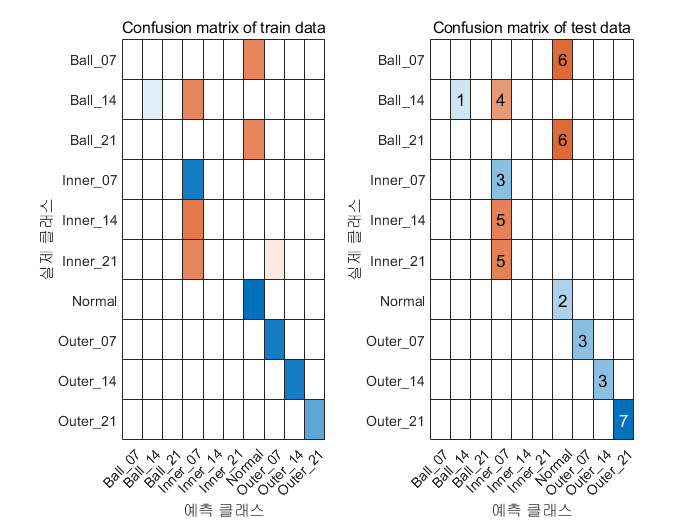

SFS_SVM_loss = 0.4381

SFS_SVM_loss = SVM(global_Train_select,global_Train_class,global_Test_select, global_Test_class)

### - Decision Tree

ResubErr_Tree = 0

cvErr_Tree = 0.0381

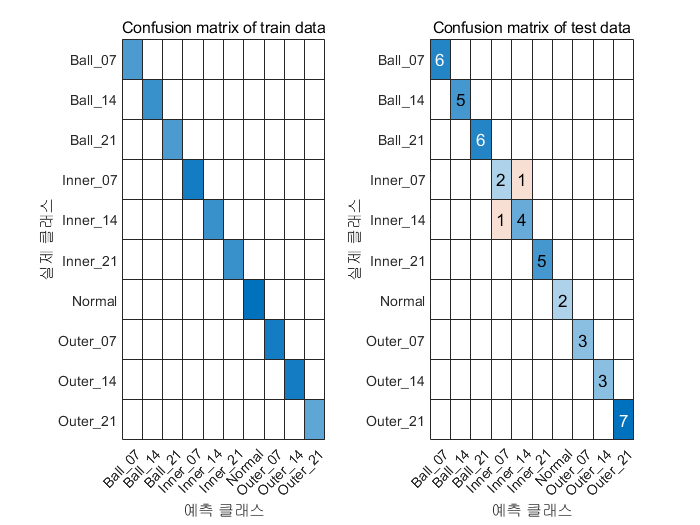

SFS_Tree_loss = 0.0571

SFS_Tree_loss = Decision_Tree(global_Train_select,global_Train_class,global_Test_select, global_Test_class)

Accuracy table

- Without selection

loss_array_without = [stat_KNN_loss stat_SVM_loss stat_Tree_loss;...
                  wp_KNN_loss wp_SVM_loss wp_Tree_loss;...
                  env_KNN_loss env_SVM_loss env_Tree_loss;...
                  pool_KNN_loss pool_SVM_loss pool_Tree_loss];
accuracy_array_without = round((1 - loss_array_without)*100,2);
model = ["1-NN [%]", "SVM [%]", "Decision Tree [%]"];
kind_without = ["Statistical", "Wavelet Package", "Complex Envelope", "Complete Pool"];

accuracy_table_without = array2table(accuracy_array_without, "VariableNames",model , "rownames", kind_without)

accuracy_table_without = 4×3 table
                        1-NN [%]    SVM [%]    Decision Tree [%]
                        ________    _______    _________________

    Statistical          90.48       92.38           91.29      
    Wavelet Package      98.91         100           97.48      
    Complex Envelope       100         100            95.1      
    Complete Pool          100         100           93.67      


- With selection

loss_array_with = [PCA_KNN_loss PCA_SVM_loss PCA_Tree_loss;...
                   SFS_KNN_loss SFS_SVM_loss SFS_Tree_loss];
accuracy_array_with = round((1 - loss_array_with)*100,2);
kind_with = ["PCA Pool" , "SFS Pool"];
accuracy_table_with = array2table(accuracy_array_with, "VariableNames",model , "rownames", kind_with)

accuracy_table_with = 2×3 table
                1-NN [%]    SVM [%]    Decision Tree [%]
                ________    _______    _________________

    PCA Pool      100          100           98.57      
    SFS Pool      100        56.19           94.29      


## Discusion

When learning using KNN in the without selection, it shows 100% accuracy except for the statistical feature and wavelet package feature.

In particular, the statistical feature shows quite low accuracy due to underfitting, so it is not suitable for the model when only statistical data is used. 

However, analysis through other features shows high accuracy. 

And when using SVM, 100% accuracy was shown in all features except for statistical features. If a model is trained without selection, it can be said that SVM is the best model.

 When learning through the Decision Tree, it has worse accuracy than other models. This data set can be said to be data that does not match the Decision Tree technique.

It shows lower accuracy than when each data is learned separately in the Complete Pool, which combines all features in the Decision Tree.

This can be suspected of overfitting.

With selection, Demension Reduction was performed using PCA and Sequential Forward Selection (SFS).

 As a result of applying each technique to the Global Pool, it showed 100% accuracy when using KNN. 

It can be seen that this is the most suitable technique for Demension Reduction in the data set. 

Decision Tree shows similar accuracy to without selection.    

It can be determined that Demension Reduction is unnecessary when using the Decision Tree. 

SVM showed 100% accuracy when using PCA technique, but very low accuracy when using SFS.

It can be determined that SFS is very unsuitable when learning the model with SVM.

Considering the reason why SVM shows low accuracy, when defining loss function, SVM is too slow to be defined as KNN, which may have been a problem, and underfitting occurred due to the small number of selected features.